# PARCISER - Projet 6.1 

## Génération de données simulées d'une SER

Le but est ici de se familiariser avec les données susceptibles d'être en sortie de l'analyseur de réseau, lors d'une série d'acquisition de la chambre anéchoïque de l'ENSTA.

La fonction gen_synth.m m'a été gracieusement donnée par le Dr. Comblet. Elle nécessite de poser plusieurs variables :

clear
xs = [-3 -1 1 1 1 1 3 5 5];
ys = [0 0 -2 -1 1 2 0 -2 2];  %Vu dans le poly de Mr Kenchaf

amps = 10.^ [ones(1,length(xs))];
map = [xs'/10 ys'/5 amps'];  %Coordonnées des points brillants, en forme d'avion, + amplitude
map2 = [[0 0.2 0.2 0]'  [0 0 0.2 0.2]'  [10 10 10 10]'];
c0 = 3e8;

Les distances à renseigner pour les map seront en mètres. Il faut aussi se rappeler aussi que la résolution en distance dépend de la largeur de bande. Ne pas prendre des points brillants dont la distance est inférieure à la résolution, mais aussi une cible dont les dimensions sont supérieures à la fenêtre d'ambiguïté.

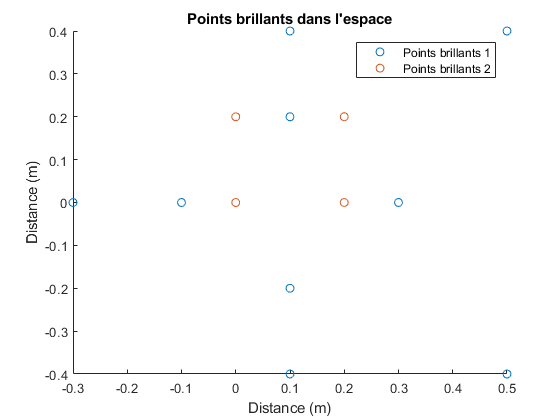

figure;
hold on
scatter(map(:,1),map(:,2),'DisplayName',"Points brillants 1")
scatter(map2(:,1),map2(:,2),'DisplayName',"Points brillants 2")
title("Points brillants dans l'espace");xlabel("Distance (m)");ylabel("Distance (m)")
legend
hold off

fmin = 8e9; fmax = 12e9; % fmin et fmax
th1 = -180; th2=180;  %angle min et max
nf = 120; nth = 360; %Nombre d'échantillons respectivement en angle, et en fréquence.
df = (fmax-fmin)/nf;
dth = (th2-th1)/nth;

freq = fmin:df:fmax-df;
angle = th1:dth:th2;

deltaR = c0/(2*(fmax-fmin));
Wd = c0/(2*df);
Wt = c0/(2*mean(freq)*dth*pi/180);

Ces variables sont posées en fonction des informations données par la page 15 de *Mesure de la SER*) 

Voyons ce que nous pouvons en faire.

sigc2 = gen_synth(map2,fmin,fmax,nf,th1,th2,nth); 
sigc = gen_synth(map,fmin,fmax,nf,th1,th2,nth);

sigc est une matrice de nf lignes, et nth colonnes.

Représentons la : 

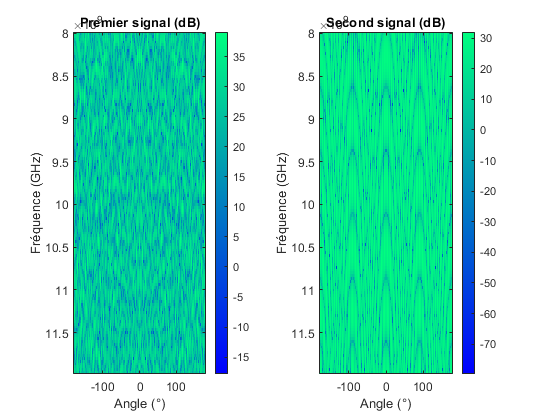

figure
subplot(121)
imagesc(angle,freq,20*log10(abs(sigc)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter; colorbar
title('Premier signal (dB)'); xlabel('Angle (°)'); ylabel('Fréquence (GHz)')
subplot(122)
imagesc(angle,freq,20*log10(abs(sigc2)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter ;colorbar
title('Second signal (dB)');xlabel('Angle (°)');ylabel('Fréquence (GHz)')

# ISAR

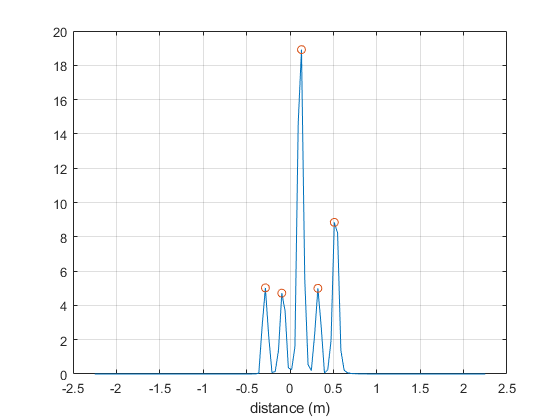

pro_dist=fftshift(ifft(sigc(:,1).*hanning(length(freq))));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist)); %
[pics,abscisses] = findpeaks(abs(pro_dist),'MinPeakProminence',2);
figure;plot(distance,abs(pro_dist),'DisplayName',"sigc");xlabel("distance (m)");ylabel("");hold on; grid on
scatter(distance(abscisses),pics)

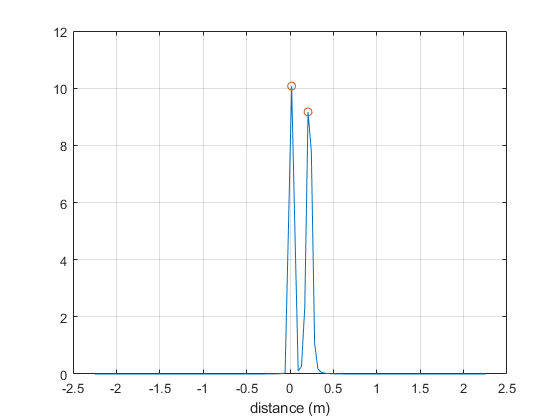

pro_dist2=fftshift(ifft(sigc2(:,1).*hanning(length(freq))));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist2));

[pics2,abscisses2] = findpeaks(abs(pro_dist2),'MinPeakProminence',2);
figure;plot(distance,abs(pro_dist2),'DisplayName',"Zero Padded");xlabel("distance (m)");ylabel("");hold on; grid on
scatter(distance(abscisses2),pics2)

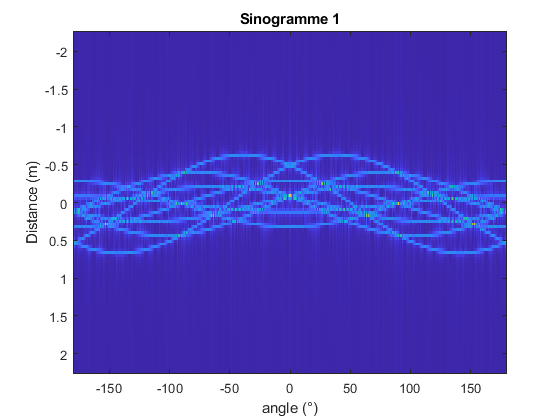

sino=fftshift(ifft(sigc),1);
figure;imagesc(angle,distance,abs(sino));xlabel("angle (°)"); ylabel("Distance (m)")
title("Sinogramme 1")

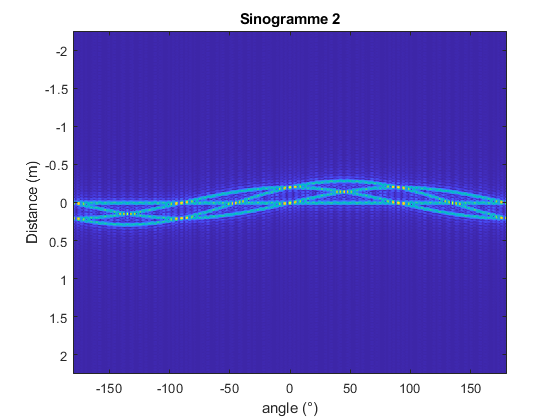

sino2=fftshift(ifft(sigc2,512),1);
figure;imagesc(angle,distance,abs(sino2));xlabel("angle (°)"); ylabel("Distance (m)"); title("Sinogramme 2")

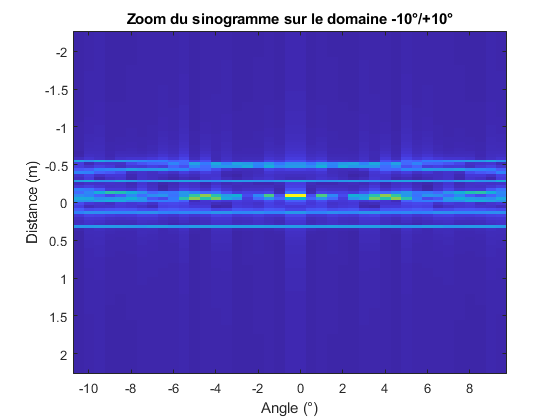

angle_debut = 170;
angle_fin = 190;
indice_debut = floor(angle_debut*nth/360);
indice_fin = floor(angle_fin*nth/360);
angles = indice_debut:indice_fin;
distanceT=linspace(-Wt/2,Wt/2,512);
zoom = sino(:,angles);

figure
imagesc(angle(angles),distance,abs(zoom))
title("Zoom du sinogramme sur le domaine -10°/+10°");xlabel("Angle (°)");ylabel("Distance (m)")

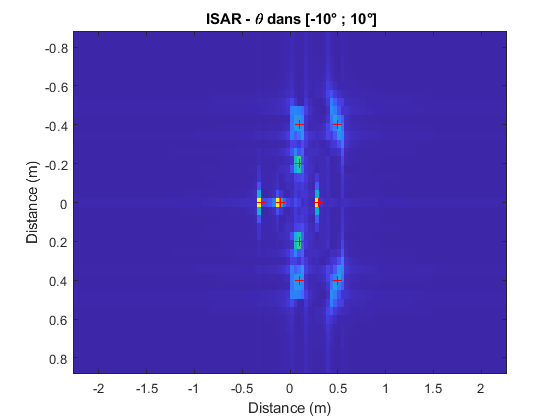

image = fftshift(fft(zoom,[],2),2);
figure
imagesc(distance,distanceT,fliplr(abs(image')));xlabel("Distance (m)");ylabel("Distance (m)")
title(" ISAR - \theta dans [-10° ; 10°]")
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red')

Notre cible apparait, cependant nous constatons que l'image n'est pas de bonne qualité et que, par exemple, les points brillants éloignés du centre de l'image sont de moins grande intensité. Pour rappel, nous avions fixé tous les points brillants à la même intensité dans les variables "map".  

## Essai de déconvolution

On peut utiliser une méthode de déconvolution aveugle pour améliorer l'image en sortie d'algo.

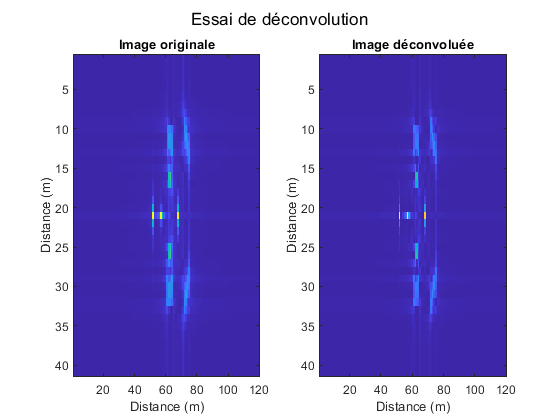

[deconv,psfr] = deconvblind(fliplr(abs(image')),ones(7,7));
figure
sgtitle("Essai de déconvolution")
subplot(121)
imagesc(fliplr(abs(image')));title("Image originale");xlabel("Distance (m)");ylabel("Distance (m)")
subplot(122)
imagesc(deconv);title("Image déconvoluée");xlabel("Distance (m)");ylabel("Distance (m)")

Nous pouvons améliorer l'image précédente en passant du repère polaire au repère cartésien. En effet, nous souhaitons représenter une image 2D, à partir d'un angle et d'une distance. Il va donc falloir interpoler les données sur une nouvelle grille.

## **Changement de repère**

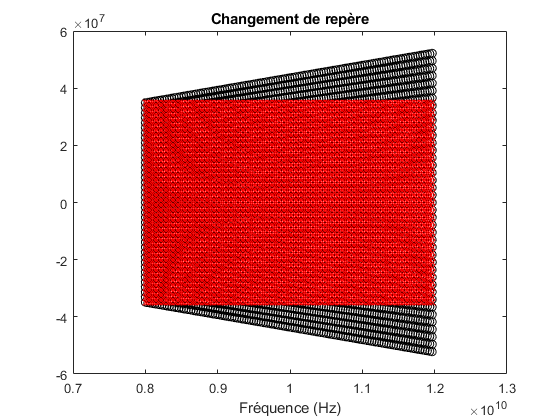

%coord cartesien
distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
f1=min(freq);f2=max(freq);
t1=-dth/2;t2=+dth/2;
fx=linspace(f1,f2,length(freq));
fy=linspace(t1,t2,length(distanceT))*pi/180;
[xi,yi]=meshgrid(fx,fy);
%coord polaire
xip=xi.*cos(yi);
yip=xi.*sin(yi);
figure;plot(xip,yip,'ob','color',"black");hold on

distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
yic=linspace(yip(1,1),yip(length(distanceT),1),length(distanceT));
xifin=sqrt(fx(1,end)^2-yic(1,end)^2);
xic=linspace(f1,xifin,length(freq));
[fx,fy]=meshgrid(xic,yic);
plot(fx,fy,'xr');xlim([fmin-1e9 fmax+1e9]); title("Changement de repère");xlabel("Fréquence (Hz)"); ylabel("")

A partir de cela, nous pouvons définir les données suivantes :  pas $\delta$kx et $\delta$ky 

dkx = (fx(1,2)-fx(1,1))*2*pi/c0;  %pas de la grille cartésienne en x
dky = (fy(2,1)-fy(1,1))*2*pi/c0;  %pas de la grille cartésienne en y
Nx = nf;  %Taille de la grille en x
Ny = (indice_fin - indice_debut +1)*dth;  %Taille de la grille en x
N = Nx * Ny;  %Nombre total d'éléments
dx = 1/(Nx*dkx);
dy = 1/(Ny*dky);

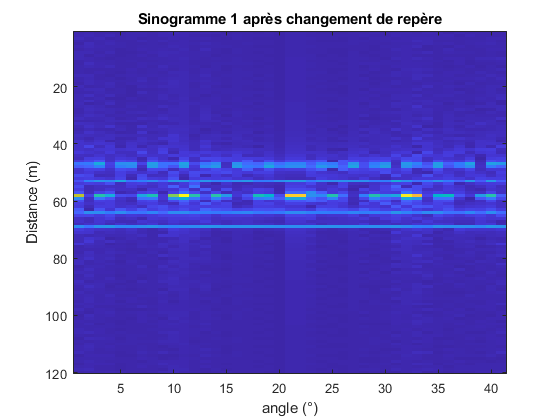

data=sigc(:,indice_debut:indice_fin);
datac=griddata(xip.',yip.',data,fx.',fy.','nearest');  %Interpolation
sino3=fftshift(ifft(datac),1);
figure;imagesc(abs(sino3));xlabel("angle (°)"); ylabel("Distance (m)");title("Sinogramme 1 après changement de repère")

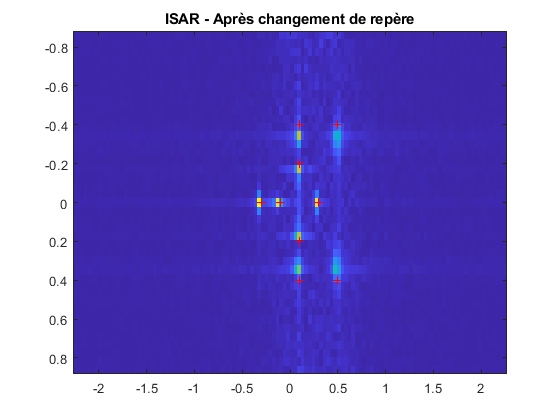

isar2 = fftshift(fft(sino3,[],2),2);
figure;imagesc(distance,distanceT,fliplr(abs(isar2')));  %Je ne sais pas pourquoi faut que je fliplr :o
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red');title("ISAR - Après changement de repère")

L'image s'en voit beaucoup plus moins "bruitée" : il y a moins d'artefacts.

## Parcimonie

Nous avons déjà un premier résultat avec l'ISAR. Essayons maintenant d'implémenter SPRITE petit à petit. 

Déjà, SPRITE se voulant parcimonieuse, il faut exprimer notre problème sous la forme suivante : $\sigma$ = **H*****a** + **n**

$\sigma$ correspond aux données de la chambre anéchoïque (il faudra peut-être la flatten) Update 05/02 : En effet il faudra que je flatten.

Dans le document "SPRITE : A New Sparse Approach for 3D High Resolution RCS Imaging", il est précisé que si l'on a nos données sur une grille cartésienne régulière (ce qui est le cas, avec la variable datac), alors **H **peut s'écrire :

H = $\alpha$ * $sqrt(N)$ * $\delta_\psi$ * $S$ * $F$ * $\delta_\phi$  

Mais, quelles sont les valeurs correspondantes ? update 8/02 ; cf p44 thèse 

Après tout, alpha et N sont juste des coeffs multiplicateurs, ça ne devrait pas non plus tout niquer si c'est égal à 1

S est la matrice de sous-échantillonage.

Construisons les vecteurs et matrices qui nous serons utiles : 

**On vectorise nos données**

flatdata = datac(:);
kx0 = (2*pi*fmin/c0)*sin(angle(indice_debut));
ky0 = (2*pi*fmin/c0)*cos(angle(indice_debut));
kx = kx0*ones(1,Nx);
ky = ky0*ones(1,Ny);
for ind = 1:Nx
    if ind<=Ny
        ky(ind) = ky(ind)+ind*dky;
    end
    kx(ind) = kx(ind)+ind*dkx;
end

**Construction de la matrice de TDF 2D**

Fy = zeros(Ny,Ny);
for i=1:Ny
    for j=1:Ny
        Fy(i,j) = exp(-2*1j*pi*(i-1)*(j-1)/Ny);
    end
end

Fx = zeros(Nx,Nx);
for i=1:Nx
    for j=1:Nx
        Fx(i,j) = exp(-2*1j*pi*(i-1)*(j-1)/Nx);
    end
end
F = kron(Fy,Fx);  %Produit de kronecker
disp(size(F)) %OOF

        2400        2400



On voit que notre matrice F a la taille correspondant à flatdatac. 

**Le coefficient de déphasage **$\alpha$** à l'origine des grilles du k-space et spatiale : **

alpha = 1;  %Je considère l'origine comme étant (0,0), pratique. 

**Matrice diagonale de déphasage **$\delta_\phi$** dans le domaine spatial :**

deltaPhix = eye(Nx);
deltaPhiy = eye(Ny);

for ind=0:Nx-1
    deltaPhix(ind+1,ind+1) = exp(-2*1j*pi*kx0*dx*ind);
end

for ind=0:Ny-1
    deltaPhiy(ind+1,ind+1) = exp(-2*1j*pi*ky0*dy*ind);
end
deltaPhi = kron(deltaPhiy,deltaPhix);

**Matrice diagonale de déphasage **$\delta_\psi$** dans le s-space :**

deltaPsi = eye(N); %Là encore, je pars du principe que mon origine est (0,0)

**Matrice S correspondant au sous-échantillonnage**

Il me semble ne pas en avoir besoin, vu que mes données sont déjà regriddées. (cf gridata)

**Enfin, la matrice H correspondant à notre modèle est : **

**(ATTENTION à la RAM et au temps de calcul si Nx et Ny grands)**

H = alpha*sqrt(N)*deltaPsi*F*deltaPhi;
hermit = conj(H');

MAINTENANT que j'ai un modèle, qui n'affiche pas des NaN +1j NaN partout, je vais essayer une simple régularisation, voir ce que ça donne. 

## **Tikhonov**

Selon le rang de la matrice, on a deux écriture. Là, H est inversible (mercé Fourier), donc son rang, c'est sa taille. Les deux écritures sont équivalentes.

lambdaTikh = 20;
resultat = inv(hermit*H + lambdaTikh*eye(length(H)))*hermit*flatdata; %Attention au temps de calcul.. 

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Related documentation

Tikh = reshape(resultat,Nx,Ny);

resultat2 = hermit*inv(H*hermit + lambdaTikh*eye(length(H)))*flatdata;
Tikh2 = reshape(resultat2,Nx,Ny);
figure
subplot(211)
imagesc(distance,distanceT,fliplr(abs(fftshift(Tikh')))); hold on
plot(map(:,1),map(:,2),'+',"Color", 'red'); hold off
subplot(212)
imagesc(distance,distanceT,fliplr(abs(fftshift(Tikh2')))); hold on
plot(map(:,1),map(:,2),'+',"Color", 'red'); hold off

Pas très concluant pour l'instant.. MAIS ça ressemble à quelque chose. ça a le mérite de ressembler à mon avion :') 

ADMM 

Alors... l'algorithme est expliqué dans le document. Seul "problème", c'est une plaie à décrypter. Il y a énormément de matrices différentes.

Update 05/02 : En fait la thèse explicite les matrices P, et Dx Dy 

Il doit certainement y avoir des simplifications, étant donné que je laisse une dimension de côté...

**Expression du critère J(a)**

On a besoin de : H, $\mu$ , P, Dx et Dy

% P = zeros(Ny,N);
% for ind = 0:Ny-1
%     P(ind+1,(ind*Ny)+1:(ind*Ny)+Ny)= ones(1,Ny);
% end
P = ones(N,1);
mu = 10;
lambda = 10;
nu = 1;


Dx0 = -1*eye(Nx) + triu(ones(Nx,Nx),1) - triu(ones(Nx,Nx),2);
Dx0(Nx,1) = 1;
Dx = kron(Dx0,eye(Ny));  %Il aurait fallu refaire un produit de kronecker avec INz, mais je suis en 2D.

Dy0 = (-1*eye(Nx) + triu(ones(Nx,Nx),1) - triu(ones(Nx,Nx),2))';
Dy0(1,Ny) = 1;
Dy = kron(eye(Nx),Dy0);

Je remarque tout de même qu'il n'y a pas de Dz en 3D... peut être qu'il n'y a pas de Dy en 2D ? Soit, passons. 

**Algorithme ADMM**

On a ici besoin d'initialiser bon nombres de variables auxiliaires. 

Empiriquement (thèse p109), les paramètres de pénalité $\rho_P$, $\rho_D$, et $\rho_C$ sont satisfaisant avec

%rhoP = Nz/2;  % A vrai dire, si je n'ai pas de z... je ne l'utilise pas :) 
rhoD = N/2;
rhoC = N/2;

les vecteurs u et v sont initialisés à 0, excepté vx, que j'initialise avec la carte ISAR déjà présente

v = [softthresh((Dx*isar2(:))',lambda/rhoD) ; zeros(1,2520)]; % = [ vx vc ]
u = [zeros(1,2520) ; zeros(1,2520)];% = [ ux uc ]

rhoP = 0 implique que les variables vp et up sont.. inexistantes (?) en 2D. 

Dy n'étant pas impliqué non plus, vy et uy disparaissent. 

il nous reste un problème clair et limpide, qu'on peut maintenant résoudre. (ahahahah)

Pour la mise à jour pratique et rapide de a, on a : 

G = hermit*H + rhoD*conj(Dx') + (nu+rhoC)*eye(N);
%rank(G) permet de s'assurer de l'inversibilité de cette matrice
invG=inv(G);

clear a
for k = 1:50
    t = rhoD*(conj(Dx')*(v(1,:)-u(1,:))' + rhoC*(v(2,:)-u(2,:))');
    d = hermit*flatdata + t; 
    
    %%%% Mise à jour de la carte %%%%
    a = invG*d;
    
    %%%% Mise à jour des variables auxiliaires initiales
    v(1,:) = softthresh(Dx*a+u(1,:)',lambda/rhoD);
    v(2,:) = a + u(2,:)';

    %%%% Mise à jour des multiplicateurs de Lagrange
    u(1,:) = (u(1,:)' + a - v(1,:)')';
    u(2,:) = (u(2,:)' + a -v(2,:)')';
end

sprite = reshape(a,Nx,Ny);
figure
imagesc(distance,distanceT,abs(fftshift(sprite')))

Update 04/02: Je viens de me rendre compte qu'il y a un truc qui s'appelle CVX, qui fait de l'optimisation. Peut-être que je peux adapter un code pour faire l'ADMM. 

CVX 

Permet de résoudre des problèmes d'optimisation convexe. Cf site de stanford pour la petite video de présentation et exemple ci-dessous.

% cvx_begin
%n = 2520;
% cvx_begin
%     variable x(n)
%     minimize( norm( H * x -flatdata, 2 ) )
%     subject to
%         norm( x, 1 ) <= 5
% cvx_end

Comparaisons : 

figure
sgtitle("Comparaison des méthodes")
subplot(221)
imagesc(distance,distanceT,deconv);title("Image PFA déconvoluée");xlabel("Distance (m)");ylabel("Distance (m)");hold on; plot(map(:,1),map(:,2),'+',"Color", 'red');
subplot(222)
imagesc(distance,distanceT,fliplr(abs(isar2')));
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red');title("ISAR - Après changement de repère");xlabel("Distance (m)");ylabel("Distance (m)")
subplot(223)
imagesc(distance,distanceT,fliplr(abs(fftshift(Tikh2')))); hold on; title("Régularisation de Tikhonov")
plot(map(:,1),map(:,2),'+',"Color", 'red'); hold off
subplot(224)
imagesc(distance,distanceT,abs(fftshift(sprite')));title("SPRITE");xlabel("Distance (m)");ylabel("Distance (m)");hold on; plot(map(:,1),map(:,2),'+',"Color", 'red');
